# 2d Hughe's Flow using 5th WENO Advection and Fast Sweep

Now that both the 5th order WENO advection and 5th order Fasts weep algorithm is up and running, I will solve a synthetic problem to ensure that they thye are working as intended together.

## Problem Definition

I will be solving the porblme where there is a rectangular slab (The one which i solved in my past with lower order schemes and see how good does the result using this new higher scheme is, comparing both of them

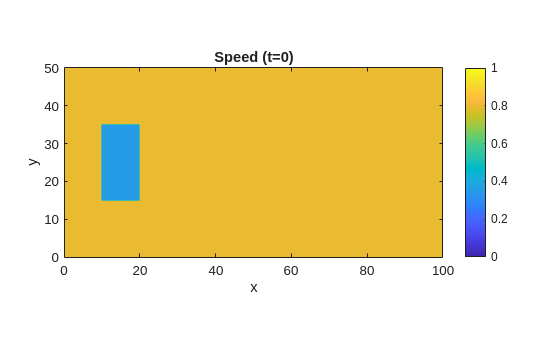

%-------Domain Parameter-----%
% Grid Points
global Nx;
global Ny;
Nx = 400;
Ny = 200;

%--Important Parameter
INFINITE = 10^2;
eta = 10^-6;
error_eta = 10^-9;

% To track the error for each iterations
iteration_error = [];

% Dimension of Domain
Lx = 100;
Ly = 50;

% Domain
x = linspace(0,Lx,Nx);
y = linspace(0,Ly,Ny);
[X,Y] = meshgrid(x,y);

% Defining velocity
global speed discomfort cost x_velocity y_velocity;

% Space Interval
global h;
h = Lx/Nx;

% Total Time
t_total = 2;
% Time Interval
dt = 0.01;

% --- Obstacle modelling ----%
obstacle = false(Ny,Nx);

%-------Initial Condition------%

% Intial Condition (Discontineous)
rho_square = 0.2*ones(size(X));
rho_square( X>=10 & X<=20 & Y>=15 & Y<=35 ) = 0.65;


%--Function to compute Velocity using Density
function speed = makeSpeed(rho)
    global Nx Ny;
    speed = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            speed(j,i) = 1 - rho(j,i);
        end
    end
end
%--Function to compute Discomfort using Density
function discomfort = makeDiscomfort(rho)
    global Nx Ny;
    discomfort = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            discomfort(j,i) = rho(j,i)*rho(j,i);
        end
    end
end
%--Function to compute Cost function using Speed and Discomfort
function cost = makeCost(speed,discomfort)
    global Nx Ny;
    cost = zeros(Ny,Nx);
    for i = 1:1:Nx
        for j = 1:1:Ny
            cost(j,i) = 1/speed(j,i) + discomfort(j,i);
        end
    end
end

speed = makeSpeed(rho_square);
discomfort = makeDiscomfort(rho_square);
cost = makeCost(speed,discomfort);

% Plotting Speed
figure(1)
contourf(X,Y,speed,'LineStyle', 'none');
title('Speed (t=0)');
clim([0,1]);
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

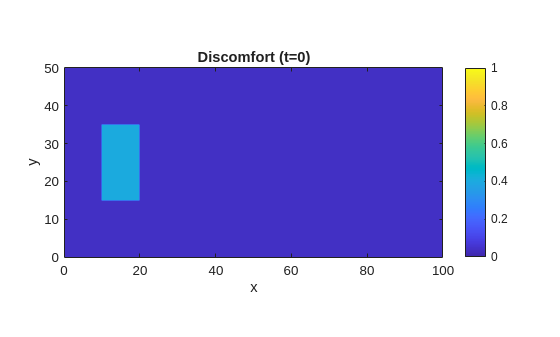

% Plotting Discomfort
figure(2)
contourf(X,Y,discomfort,'LineStyle', 'none');
title('Discomfort (t=0)');
clim([0,1]);
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

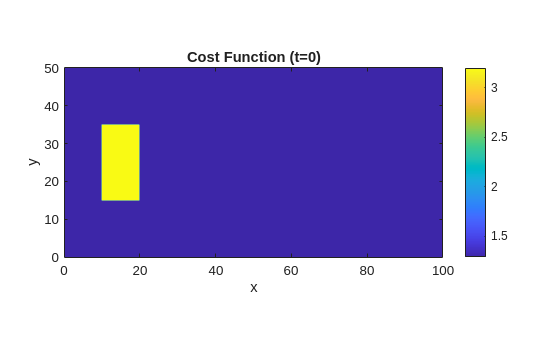

% Plotting Cost Function
figure(3);
contourf(X,Y,cost,'LineStyle', 'none');
title('Cost Function (t=0)');
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

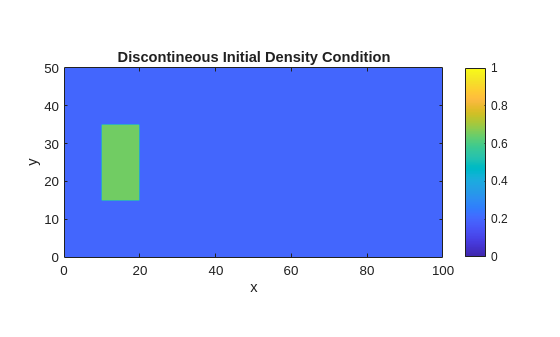

% Plotting the Initial Condition
figure(4);
contourf(X,Y,rho_square,'LineStyle', 'none');
title('Discontineous Initial Density Condition');
clim([0,1]);
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');

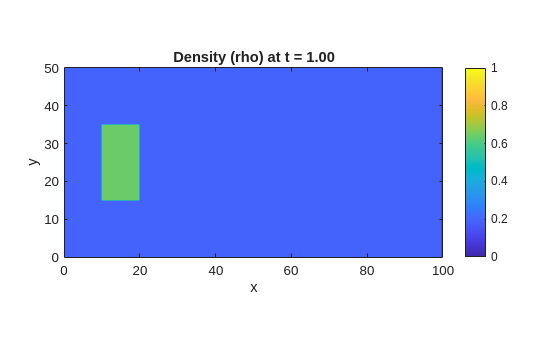

%-- Function that will calculate the flux depending on the u,v and Density.
% X_velocity and y_velocity will be found using the potential.
function flux = makeFlux(rho,x_velocity,y_velocity)
    global Nx Ny;

    % Initialzing Flux
    flux_x = zeros(Ny,Nx);
    flux_y = zeros(Ny,Nx);
    flux = zeros(2, Ny, Nx);

    for i = 1:1:Nx
        for j = 1:1:Ny
            flux_x(j,i) = rho(j,i) * x_velocity(j,i);
            flux_y(j,i) = rho(j,i) * y_velocity(j,i);

            flux(1,j,i) = flux_x(j,i);
            flux(2,j,i) = flux_y(j,i);
        end
    end 
end


rho = rho_square;

%--Preallocating the memory
rho_n = zeros(Ny,Nx);
rho_1 = zeros(Ny,Nx);
rho_2 = zeros(Ny,Nx);
rho_next = zeros(Ny,Nx);

%-----------MAIN SOLVER------------%
for t = 1:dt:t_total

    % Computing Cost For the density rho
    speed = makeSpeed(rho);
    discomfort = makeDiscomfort(rho);
    cost = makeCost(speed,discomfort);

    %-- Calculate Initial Phi guess using Lower order Fast Sweep
    phi_first_order = First_order_Godunov_Fast_Sweep_Algorithm(cost,h,Nx,Ny,obstacle,INFINITE);
   %-- Calculate The final phi using higher ordfer scheme and above intial guess 
    phi = weno_fastsweep(cost,h,Nx,Ny,obstacle,eta,error_eta,INFINITE,phi_first_order,iteration_error);

    %--Calculate the Components of Velocity
    [phi_x, phi_y] = gradient(phi, h, h); % partial derivatives of phi in x and y
    mag_phi = sqrt(phi_x.^2 + phi_y.^2);
    mag_phi = max(mag_phi, eta);          % To be safe with denominator
    for i = 1:1:Nx
        for j = 1:1:Ny
            x_velocity(j,i) = speed(j,i) * (phi_x(j,i))/mag_phi(j,i);
            y_velocity(j,i) = speed(j,i) * (phi_y(j,i))/mag_phi(j,i);
        end
    end

    % -- Making rho_n and RHS of rho_n
    rho_n = rho;
    semi_discritze_form_rho_n = makeRHS(rho_n);
    


    % ---------- Makign the RHO_1 and then RHS of rho_1 ------ %
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2
            rho_1(j,i) = rho_n(j,i) + dt * semi_discritze_form_rho_n(j-3,i-3);
        end
    end
    % -- Extrapolation (My Intuition)
    rho_1(:,3) = rho_1(:,4); rho_1(:,2) = rho_1(:,3); rho_1(:,1) = rho_1(:,2);  % Right Edge
    rho_1(3,:) = rho_1(4,:); rho_1(2,:) = rho_1(3,:); rho_1(1,:) = rho_1(2,:);  % Bottom Edge
    rho_1(Ny-1,:) = rho_1(Ny-2,:); rho_1(Ny,:) = rho_1(Ny-1,:);                 % Top Edge
    rho_1(:,Ny-1) = rho_1(:,Ny-2); rho_1(:,Ny) = rho_1(:,Ny-1);                 % Left Edge
    % -- RHS of discritised form using rho_1
    semi_discritze_form_rho_1 = makeRHS(rho_1);



    %--------- Making the RHO_2 and RHS of RHO_2 ----------%
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2
            rho_2(j,i) = 3/4 * rho_n(j,i) + 1/4 * (rho_1(j,i) + dt * semi_discritze_form_rho_1(j-3,i-3));
        end
    end
    % -- Extrapolation (My Intuition)
    rho_2(:,3) = rho_2(:,4); rho_2(:,2) = rho_2(:,3); rho_2(:,1) = rho_2(:,2);  % Right Edge
    rho_2(3,:) = rho_2(4,:); rho_2(2,:) = rho_2(3,:); rho_2(1,:) = rho_2(2,:);  % Bottom Edge
    rho_2(Ny-1,:) = rho_2(Ny-2,:); rho_2(Ny,:) = rho_2(Ny-1,:);                 % Top Edge
    rho_2(:,Ny-1) = rho_2(:,Ny-2); rho_2(:,Ny) = rho_2(:,Ny-1);                 % Left Edge
    % -- RHS of discritised form using rho_2
    semi_discritze_form_rho_2 = makeRHS(rho_2);


    %----------Making the rho_next-------------------------%
    
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2
            rho_next(j,i) = 1/3 * rho_n(j,i) + 2/3 * (rho_2(j,i) + dt * semi_discritze_form_rho_2(j-3,i-3));
        end
    end    
    % -- Extrapolation (My Intuition)
    rho_next(:,3) = rho_next(:,4); rho_next(:,2) = rho_next(:,3); rho_next(:,1) = rho_next(:,2);    % Right Edge
    rho_next(3,:) = rho_next(4,:); rho_next(2,:) = rho_next(3,:); rho_next(1,:) = rho_next(2,:);    % Bottom Edge
    rho_next(Ny-1,:) = rho_next(Ny-2,:); rho_next(Ny,:) = rho_next(Ny-1,:);                         % Top Edge
    rho_next(:,Ny-1) = rho_next(:,Ny-2); rho_next(:,Ny) = rho_next(:,Ny-1);                         % Left Edge

    %--Ploting the rho_next;
    if mod(round(t/dt),10) == 0
        figure(6);
        contourf(x, y, rho_next, 20, 'LineColor', 'none');
        colorbar;
        clim([0 1]);
        title(sprintf('Density (rho) at t = %.2f', t));
        xlabel('x'); ylabel('y');
        axis equal tight; 
        drawnow;
    end

    % Substituting back the rho value \
    rho = rho_next;  
end

## First order Godunov Fast Sweep Algorithm (Older Version)

function phi = First_order_Godunov_Fast_Sweep_Algorithm(c,h,Nx_dash,Ny_dash,obstacle_dash,INFINITE)
    %---------------------------------------------
    % Initialization
    %---------------------------------------------
    phi = INFINITE*ones(Ny_dash, Nx_dash);    % Initial potential field
    phi(:,Nx_dash) = 0;                       % Exit Boundary (Right)

    % Set phi inside obstacle to Inf
    phi(obstacle_dash) = INFINITE;

    %---------------------------------------------
    % Fast Sweeping Iterations
    %---------------------------------------------
    for sweep = 1:20
        % === Sweep 1: i→, j→
        for i = 2:Nx_dash-1
            for j = 2:Ny_dash-1
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
        % === Sweep 2: i←, j→
        for i = Nx_dash-1:-1:2
            for j = 2:Ny_dash-1
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
        % === Sweep 3: i←, j←
        for i = Nx_dash-1:-1:2
            for j = Ny_dash-1:-1:2
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
        end
       % === Sweep 4: i→, j←
       for i = 2:Nx_dash-1
            for j = Ny_dash-1:-1:2
                if ~obstacle_dash(j, i)
                    phi = update_phi(phi, c, i, j, h);
                end
            end
       end

       phi(:,1) = phi(:,2);                % Left
       phi(1, :) = phi(2, :);              % Top
       phi(Ny_dash, :) = phi(Ny_dash-1,:); % Bottom

    end
    
end

% Subfunction: Update one grid point using Godunov scheme

function phi = update_phi(phi, c_, i, j, dx)
    a = min(phi(j, i-1), phi(j, i+1)); % x-direction neighbors
    b = min(phi(j-1, i), phi(j+1, i)); % y-direction neighbors
    c = c_(j, i); % Local inverse speed
    if abs(a - b) >= c * dx
        phi(j, i) = min(a, b) + c * dx;
        else
            inside = 2 * (c * dx)^2 - (a - b)^2;
        if inside >= 0
            phi(j, i) = (a + b + sqrt(inside)) / 2;
        end
    end
end


## WENO FAST SWEEP



function phi = weno_fastsweep(c,h,Nx_dash,Ny_dash,obstacle_dash,eta,error_eta,INFINITE,initial_guess,iteration_error)
    % Phi is intialised with infinity
    phi = initial_guess;
    phi_old = INFINITE * ones(size(phi));

    % Iterations
    iterations = 0;
    loop_safety = 0;

    % Exit
    phi(:,Nx_dash) = 0;

    % Iterations
    while (sum(abs(phi(:)-phi_old(:))) > error_eta && loop_safety<100)

        %fprintf("Iteration = %d ",iterations);
        err = sum(abs(phi(:)-phi_old(:)));
        %fprintf("Error = %0.10f\n",err);

        phi_old = phi;
        iterations = iterations + 1;
        iteration_error(iterations) = err;
        loop_safety = loop_safety + 1;

        for sweep = 1:4
            switch sweep
                case 1 
                    ix = 3:1:Nx_dash-2; jy = 3:1:Ny_dash-2;
                case 2 
                    ix = 3:1:Nx_dash-2; jy = Ny_dash-2:-1:3;
                case 3 
                    ix = Nx_dash-2:-1:3; jy = 3:1:Ny_dash-2;
                case 4 
                    ix = Nx_dash-2:-1:3; jy = Ny_dash-2:-1:3;
            end

            

            for i = ix
                for j = jy
                    %if the point is outside the obstacle
                    if(~obstacle_dash(j,i))
                        %------------Calcualting the phix_min---------_%

                        r_back = (eta + (phi(j,i) - 2*phi(j,i-1) + phi(j,i-2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j,i+1) + phi(j,i+2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
    
                        % Calculate the w
                        w_front = 1/(1+2*(r_front^2));
                        w_back = 1/(1+2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phix_minus = (1-w_back)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_back*((3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2))/(2*h));
                        phix_plus = (1-w_front)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_front*((-3*phi(j,i)+4*phi(j,i+1)-phi(j,i+2))/(2*h));
                        
                        
                        phix_min = min((phi(j,i) - h*phix_minus),(phi(j,i) + h*phix_plus));
                        
                        %-----------calculating the phiy_min---------%

                        r_back = (eta + (phi(j,i) - 2*phi(j-1,i) + phi(j-2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
                        r_front = (eta + (phi(j,i) - 2*phi(j+1,i) + phi(j+2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
    
                        % Calculate the w
                        w_front = 1 / (1 + 2*(r_front^2));
                        w_back = 1 / (1 + 2*(r_back^2));
    
                        % Dell phi by Dell x plus and minus
                        phiy_minus = (1-w_back) * ((phi(j+1,i)-phi(j-1,i))/(2*h)) + w_back * ((3*phi(j,i) - 4*phi(j-1,i) + phi(j-2,i))/(2*h));
                        phiy_plus = (1-w_front) * ((phi(j+1,i) - phi(j-1,i))/(2*h)) + w_front * ((-3*phi(j,i) + 4*phi(j+1,i) - phi(j+2,i))/(2*h));
                        
                        
                        phiy_min = min((phi(j,i) - h*phiy_minus), (phi(j,i) + h*phiy_plus));

                        if abs(phix_min - phiy_min) >= c(j,i)*h
                            phi(j,i) = min(phiy_min,phix_min) + c(j,i)*h;
                        else
                            phi(j,i) = ((phix_min + phiy_min) + (2*(c(j,i)*h)^2 - (phix_min - phiy_min)^2)^0.5)/2;
                        end
                    % If the point is inside the obstacle
                    else 
                        phi(j,i) = INFINITE;
                    end
                end
            end

            %------Extrapolation------%

            % Bottom edge %
            %phi(2,:) = phi(3,:);
            %phi(1,:) = phi(3,:);
            % Top edge %
            %phi(Ny_dash,:) = phi(Ny_dash-2,:);
            %phi(Ny_dash-1,:) = phi(Ny_dash-2,:);
            % Right edge %
            %phi(:,Nx_dash-1) = phi(:,Nx_dash-2);
            % Left edge %
            %phi(:,2) = phi(:,3);
            %phi(:,1) = phi(:,3);
        end   
    end
end


## RHS of Semi Discritize Form

function semi_discrite_form =  makeRHS(rho)
    global Nx Ny x_velocity y_velocity h;
    semi_discrite_form = zeros(Ny-5,Nx-5);

    %--Flux for the given rho distribution
    flux = makeFlux(rho,x_velocity,y_velocity);
    flux_x = squeeze(flux(1,:,:));
    flux_y = squeeze(flux(2,:,:));

    % Calculating the maximum speed
    alpha_x = max(abs(x_velocity(:)));
    alpha_y = max(abs(y_velocity(:)));


    % -- Calculating the value of f+ and f- at {i+2,i+1,i,i-1,i-2,i-3} -- %
    fx_negative_whole = zeros(Ny,Nx);
    fx_positive_whole = zeros(Ny,Nx);
    fy_negative_whole = zeros(Ny,Nx);
    fy_positive_whole = zeros(Ny,Nx);

    fx_negative_half = zeros(Ny-5,Nx-5);
    fx_positive_half = zeros(Ny-5,Nx-5);
    fy_negative_half = zeros(Ny-5,Nx-5);
    fy_positive_half = zeros(Ny-5,Nx-5);

    for j = 1:1:Ny
        for i=1:1:Nx
            fx_positive_whole(j,i) = 1/2 * (flux_x(j,i) + alpha_x*rho(j,i));
            fx_negative_whole(j,i) = 1/2 * (flux_x(j,i) - alpha_x*rho(j,i));
            fy_positive_whole(j,i) = 1/2 * (flux_y(j,i) + alpha_y*rho(j,i));
            fy_negative_whole(j,i) = 1/2 * (flux_y(j,i) - alpha_y*rho(j,i));
        end
    end
    
    % -- Computing the RHS of Semi Discrite form.
    for i = 4:1:Nx-2
        for j = 4:1:Ny-2

            %--X--%

            % fx{+}_[i+1/2,j]
            fx_plus_x_half_forward = stencil( ...
                fx_positive_whole(j,i-2), ...
                fx_positive_whole(j,i-1), ...
                fx_positive_whole(j,i), ...
                fx_positive_whole(j,i+1), ...
                fx_positive_whole(j,i+2));
            
            % fx{+}_[i-1/2,j]
            fx_plus_x_half_backward = stencil( ...
                fx_positive_whole(j,i-3), ...
                fx_positive_whole(j,i-2), ...
                fx_positive_whole(j,i-1), ...
                fx_positive_whole(j,i), ...
                fx_positive_whole(j,i+1));

            % fx{-}_[i+1/2,j]
            fx_minus_x_half_forward = stencil( ...
                fx_negative_whole(j,i+2), ...
                fx_negative_whole(j,i+1), ...
                fx_negative_whole(j,i), ...
                fx_negative_whole(j,i-1), ...
                fx_negative_whole(j,i-2));
            
            % fx{-}_[i-1/2,j]
            fx_minus_x_half_backward = stencil( ...
                fx_negative_whole(j,i+1), ...
                fx_negative_whole(j,i), ...
                fx_negative_whole(j,i-1), ...
                fx_negative_whole(j,i-2), ...
                fx_negative_whole(j,i-3));

            %--Y--%

            % fy{+}_[i,j+1/2]
            fy_plus_y_half_forward = stencil( ...
                fy_positive_whole(j-2,i), ...
                fy_positive_whole(j-1,i), ...
                fy_positive_whole(j,i), ...
                fy_positive_whole(j+1,i), ...
                fy_positive_whole(j+2,i));
            
            % fy{+}_[i,j-1/2]
            fy_plus_y_half_backward = stencil( ...
                fy_positive_whole(j-3,i), ...
                fy_positive_whole(j-2,i), ...
                fy_positive_whole(j-1,i), ...
                fy_positive_whole(j,i), ...
                fy_positive_whole(j+1,i));

            % fy{-}_[i,j+1/2]
            fy_minus_y_half_forward = stencil( ...
                fy_negative_whole(j+2,i), ...
                fy_negative_whole(j+1,i), ...
                fy_negative_whole(j,i), ...
                fy_negative_whole(j-1,i), ...
                fy_negative_whole(j-2,i));
            
            % fy{-}_[i,j-1/2]
            fy_minus_y_half_backward = stencil( ...
                fy_negative_whole(j+1,i), ...
                fy_negative_whole(j,i), ...
                fy_negative_whole(j-1,i), ...
                fy_negative_whole(j-2,i), ...
                fy_negative_whole(j-3,i));
            
            fx_positive_half = fx_plus_x_half_forward + fx_minus_x_half_forward;
            fx_negative_half = fx_plus_x_half_backward + fx_minus_x_half_backward;
            fy_positive_half = fy_plus_y_half_forward + fy_minus_y_half_forward;
            fy_negative_half = fy_plus_y_half_backward + fy_minus_y_half_backward;

            % Computing RHS of Semi Discritized form
            semi_discrite_form(j-3,i-3) = - 1/h * (fx_positive_half - fx_negative_half) - 1/h * (fy_positive_half - fy_negative_half);    
        end
    end
end


## WENO Advection Stencil

% To compute f half. Order of input matters
function f = stencil(f1,f2,f3,f4,f5)

    eta = 10^-6;

    % Compute S values
    s_1 = ((1/3) * f1) + ((-7/6) * f2) + ((11/6) * f3);
    s_2 = ((-1/6) * f2) + ((5/6) * f3) + ((1/3) * f4);
    s_3 = ((1/3) * f3) + ((5/6) * f4) + ((-1/6) * f5);

    % Compute Beta
    beta_1 = 13/12 * (f1 - 2*f2 + f3)^2 + 1/4 * (f1 - 4*f2 + 3*f3)^2;
    beta_2 = 13/12 * (f2 - 2*f3 + f4)^2 + 1/4 * (f2 - f4)^2;
    beta_3 = 13/12 * (f3 - 2*f4 + f5)^2 + 1/4 * (3*f3 - 4*f4 + f5)^2;

    % Definign Gamma
    gamma_1 = 1/10;
    gamma_2 = 3/5;
    gamma_3 = 3/10;

    % Computing weights bar
    w_1_dash = ( gamma_1 ) ./ ((eta + beta_1)^2);
    w_2_dash = ( gamma_2 ) ./ ((eta + beta_2)^2);
    w_3_dash = ( gamma_3 ) ./ ((eta + beta_3)^2);

    % Computing Weights
    w_1 = ( w_1_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_2 = ( w_2_dash ) / (w_1_dash + w_2_dash + w_3_dash);
    w_3 = ( w_3_dash ) / (w_1_dash + w_2_dash + w_3_dash);

    % Computing Flux
    f = w_1 * s_1 + w_2 * s_2 + w_3 * s_3;
end